## Metodo de Euler

Probando el metodo de euler con la funcion 'ejemplo1':


$$y^{\prime } \left(t\right)=\left(1-2t\right)y\left(t\right)$$


para:


$$y\left(0\right)=1$$


Metodo de euler para N=8

[x,y] = euler('ejemplo1',0,3,8,1)

x =          0
    0.3750
    0.7500
    1.1250
    1.5000
    1.8750
    2.2500
    2.6250
    3.0000


y =     1.0000
    1.3750
    1.5039
    1.2219
    0.6491
    0.1623
   -0.0051
    0.0016
   -0.0009


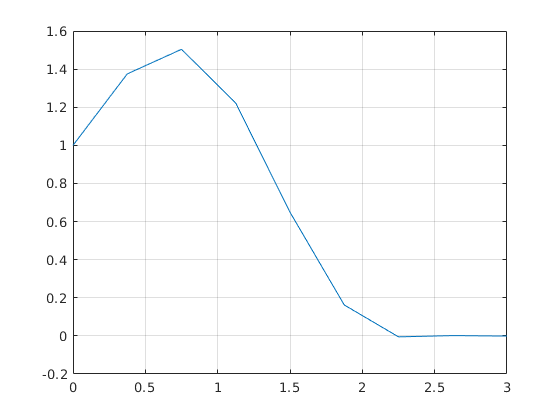

plot(x,y)
grid on

#### Calculando el error:

Solucion exacta $y\left(t\right)=e^{\frac{1}{4}-{\left(\frac{1}{2}-t\right)}^2 }$

sol_exacta=exp(1/4-(1/2-x).^2);
error=abs(sol_exacta-y)

error =          0
    0.1109
    0.2977
    0.3531
    0.1768
    0.0316
    0.0651
    0.0125
    0.0034


Error maximo para N=8

error8=max(error)

error8 = 0.3531

Metodo de euler para N=16

[x,y] = euler('ejemplo1',0,3,16,1) 

x =          0
    0.1875
    0.3750
    0.5625
    0.7500
    0.9375
    1.1250
    1.3125
    1.5000
    1.6875


y =     1.0000
    1.1875
    1.3267
    1.3888
    1.3563
    1.2291
    1.0275
    0.7867
    0.5470
    0.3419


sol_exacta=exp(1/4-(1/2-x).^2);
error=abs(sol_exacta-y)

error =          0
    0.0229
    0.0625
    0.1098
    0.1501
    0.1688
    0.1587
    0.1231
    0.0746
    0.0284


error16=max(error)

error16 = 0.1688

error8/error16

ans = 2.0919

Calculando para N=32

[x,y] = euler('ejemplo1',0,3,32,1);
sol_exacta=exp(1/4-(1/2-x).^2);
error=abs(sol_exacta-y);
error32=max(error)

error32 = 0.0819

error16/error32

ans = 2.0605